# **UPMC Data Processing Demonstration Script**

## **Basic Example**

#### Load Data and Create Data Store

[clean_table, imputed_table, day_table, SCDF_matrix] = construct_tables;
data_store = Nedoc_Data(clean_table, imputed_table, day_table, SCDF_matrix)

data_store =   Nedoc_Data with properties:

       T_cln: [32181×9 table]
       T_imp: [35328×9 table]
       T_day: [736×8 table]
           X: [1×1 struct]
         X_t: [1×1 struct]
           y: [1×1 struct]
          yp: [1×1 struct]
       today: []
    cls_defs: [16×48 double]
           L: [1×1 struct]


clear SCDF_matrix

Clean Table

- faithful to original data set

- cut dataset down to predictors and responses

- extra features, such as month and weekday, along with their non-numeric descriptors

- cut out repeated data points

- regression set ( 32181 samples )

Imputed Table

- filled holes in data set such that each day has 48 observations

- same layout as Clean Table

- regression set ( 35329 samples )

Day Table

- consists of one sample per day

- each day is classified by a score curve, defined in the SCDF Matrix

- classification set ( 736 samples )

Score Curve Definition Matrix (SCDF Matrix)

- consists entirely of score values

- 16 rows, one for each day class

- 48 columns, so each class has 48 score values to define score curves

#### Set Train/Test Split

data_store = data_store.setToday(0.75)

data_store =   Nedoc_Data with properties:

       T_cln: [32181×9 table]
       T_imp: [35328×9 table]
       T_day: [736×8 table]
           X: [1×1 struct]
         X_t: [1×1 struct]
           y: [1×1 struct]
          yp: [1×1 struct]
       today: [1×1 struct]
    cls_defs: [16×48 double]
           L: [1×1 struct]



% [X_train, y_train] = data_store.getmats('train','imp','time');
% [X, y] = data_store.getmats('all','imp','time');

Set split for training set and testing set

- X_train and y_train contain predictors and responses for each training sample

- X and y contain predictors and responses for all data samples

#### Train Model

Currently done outside Demo Sheet

#### Store Predictions

data_store = data_store.setResp(y_prediction);

Plot Predictions

fprintf('\n======================================================================================');

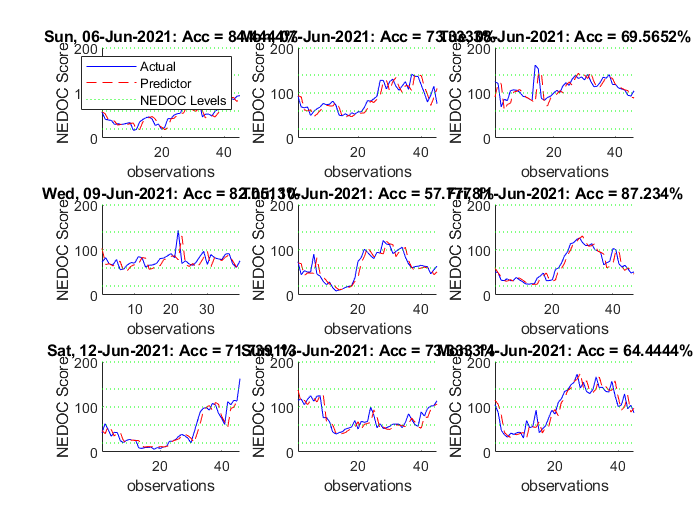

[~,accavg] = data_store.plot('Predictions (1 month before)', '06/06/2021', 9, 'TimeFrame','days', 'Field','imp');

fprintf('Average Accuracy = %.2f%%\n\n\n',accavg);

Average Accuracy = 73.77%





fprintf('\n======================================================================================');

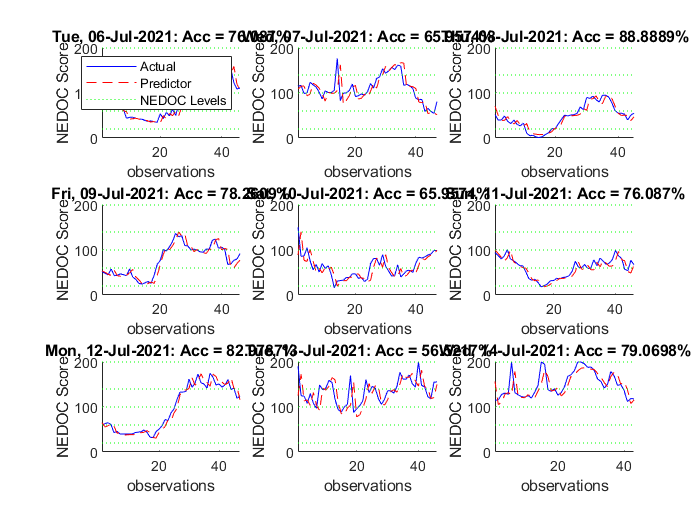

[~,accavg] = data_store.plot('Predictions (tomorrow)', '07/06/2021', 9, 'TimeFrame','days', 'Field','imp');

fprintf('Average Accuracy = %.2f%%\n\n\n',accavg);

Average Accuracy = 74.42%





fprintf('\n======================================================================================');

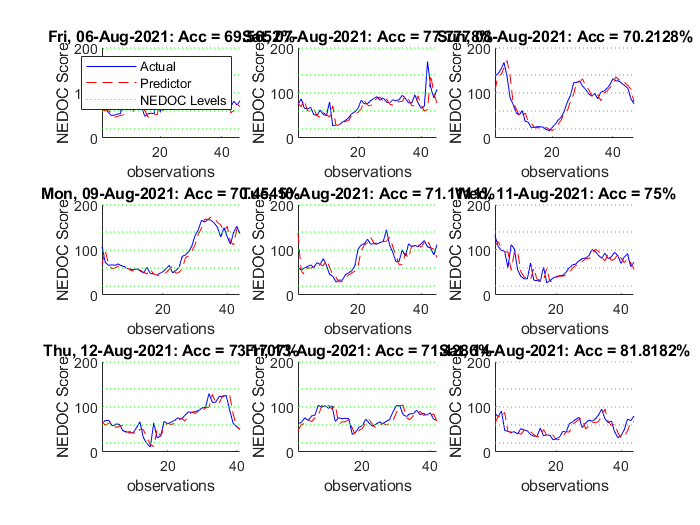

[~,accavg] = data_store.plot('Predictions (1 month later)', '08/06/2021', 9, 'TimeFrame','days', 'Field','imp');

fprintf('Average Accuracy = %.2f%%\n\n\n',accavg);

Average Accuracy = 73.39%


